p1 = rand([3 1])*10;
k = rand([3 1]);
k = k/norm(k);
theta = rand*2*pi-pi

theta = -0.9558


p2 = rot(k,theta)*p1;

subproblem1(p1,p2,k)

ans = -0.9558

t = subproblem1_linear(p1,p2,k)

t = -0.9558

sp1_error(p1, p2, k, t)

ans = 0

p1 = rand([3 1])*rand*10;
k = rand([3 1]);
k = k/norm(k);
theta = rand*2*pi-pi

theta = 3.0688


%p2 = rot(k,theta)*p1;
p2 = rand([3 1])*rand*10;

t = subproblem1_linear(p1,p2,k)

t = -0.9230

sp1_error(p1, p2, k, t)

ans = 1.2989

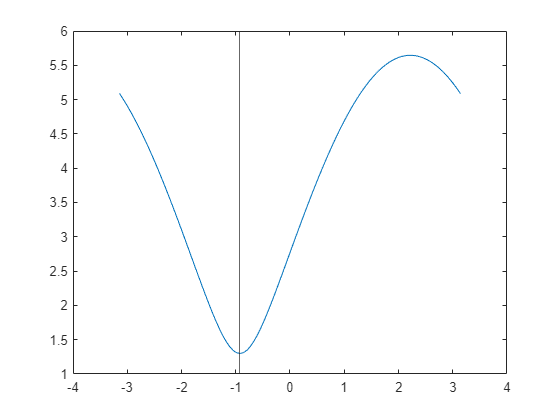


t_test = linspace(-pi, pi, 100);
e_test = NaN(size(t_test));
for i = 1:length(t_test)
    e_test(i) = sp1_error(p1, p2, k, t_test(i));
end

plot(t_test, e_test);
xline(t);

function e = sp1_error(p1, p2, k, theta)
    e = norm(p2 - rot(k, theta)*p1);
end